`集合是指具有某种特定性质的具体的或抽象的对象汇总而成的集体。其中，构成集合的这些对象则称为该集合的元素。集合中的元素具有三个性质：确定性（给定一个集合，任给一个元素，都可以确定该元素是否属于该集合）、互异性（任何两个元素都是不相同的）和无序性（每个元素的地位都是相同的，元素之间是没有顺序的）。`

`学过`Python`的同学应该知道，`Python`中可以使用`set`函数或者大括号来创建集合。然而在现版本的`MATLAB`中，还没有正式推出集合这个数据结构。目前`MATLAB`使用普通的数组来模拟集合的功能，但大家要清楚，数组中的元素可以相同而且是有先后顺序的，因此不满足集合中元素的互异性和无序性，因此数组并不能当成真正的集合。`MATLAB`官网列举了一些集合运算相关的函数，官方是这样介绍集合运算的：``集合运算比较两个集合中的元素，以找出共性或差异``。大家一定要注意，官方所说的集合要当作普通的数组来理解，用户可以通过`MATLAB`提供的与集合运算相关的函数来实现集合中的大多数操作。`

`我们先通过表格来展示这一小节要学到的函数：`

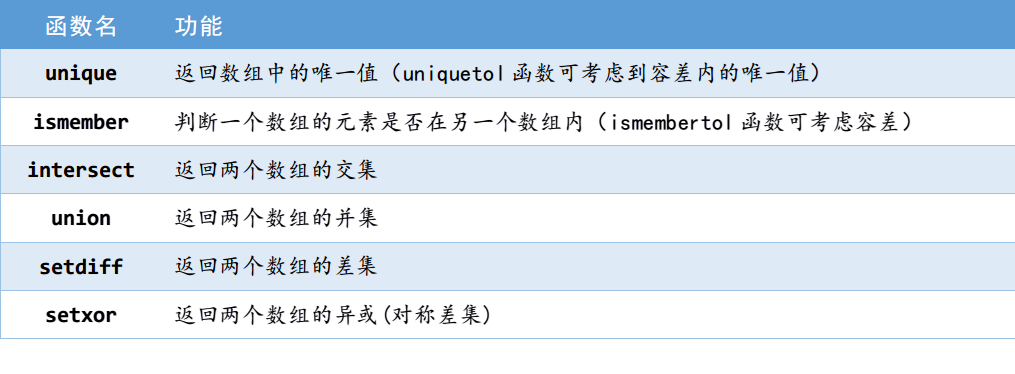

### `（`**1**`）`**unique**`函数`

**unique**`函数可用来提取数组中的唯一值，它可以用在我们学过的向量和矩阵上，也可以用在我们未来章节要学的表格上。`

`我们先以向量为例进行讲解：`

unique`函数可用来提取数组中的唯一值，它可以用在我们学过的向量和矩阵上，也可以用在我们后续章节要学的表格上。`

`我们先以向量为例进行讲解：`

`C = unique(A) ``会对向量``A``进行去重操作，``C``中的每一个元素都来自向量``A``且互不相同，同时，``MATLAB``会自动将``C``进行排序。`

A1 = [5 -6 5 10 8 -6 -3 -3];
C1 = unique(A1)

A2 = [1:5,3:-1:1];
C2 = unique(A2)

A3 = [5;1;3;1;3;5;3];
C3 = unique(A3)

`另外，unique``函数可以有最多三个返回值：``[C,ia,ic] = unique(A)`

`这里的``ia``和``ic``都是索引向量: `

- `ia是C``中的每个元素在``A``中的索引值`

- `ic是``A``中的每个元素在``C``中的索引值`

`因此有下面的等式成立：``A(ia)``等于``C ``且 ``C(ic)``等于``A``。`

A = [5 -6 5 10 8 -6 -3 -3];
[C,ia,ic] = unique(A)

ia = [2;7;1;5;4] 是一个列向量：第一个元素2代表的含义是C中第一个元素-6在A中的索引值是2（A中有两个-6，MATLAB默认返回第一个-6的索引）；第二个元素是7，表示C中第二个元素-3在A中的索引值是7；第三个元素是1，表示C中第三个元素5在A中的索引值是1；剩下的5和4代表类似的含义。

A(ia)  % 等于C

ic = [3;1;3;5;4;1;2;2]也是是一个列向量：第一个元素3代表的含义是A中第一个元素5在C中的索引值是3；第二个元素1代表的含义是A中第二个元素-6在C中的索引值是1,……

C(ic)  % 等于A

`上面得到的`C`向量都会自动进行排序，我们可以指定一个输入参数`'stable'`，这样会按照与`A`中相同的顺序返回`C`中的值。`

A = [5 -6 5 10 8 -6 -3 -3];
C = unique(A,'stable')
A = [5 -6 5 10 8 -6 -3 -3];
[C,ind] = unique(A,'stable')

unique还可以作用到矩阵上，如果A是一个矩阵，那么unique(A)的结果和unique(A(:))的结果相同。

A = [3     5
    6     8
    3     5
    4     1
    2     8
    2     5
    4     1];
C = unique(A)   % 等价于unique(A(:))

但是，如果我们加一个输入参数'rows'，那么unique(A, 'rows')会将A的每一行视为一个整体，会返回A中的唯一行。

C = unique(A,'rows')

`如果希望按照与A中相同的顺序返回唯一值，则可以在输入的最后加一个参数'stable'。`

C = unique(A,'rows','stable')

unique`函数用于矩阵上时，也可以有最多三个返回值，但这种情况我们用的非常少`

A
[C,id1,id2] = unique(A)  % 返回的索引是线性索引
A
[C,id1,id2] = unique(A,'rows')  % 返回的索引是行索引

### `（2）``ismember函数`

h = ismember(A,B)`可以判断数组`A`中的元素是否在数组`B`内，`h`是和`A`同等大小的逻辑数组，为逻辑`1`时说明该位置的`A`元素在`B`中存在，为逻辑`0`时说明在`B`中不存在。`

A = [4 1 3 4 8];
B = [3 7 4 5 4 9 6];
h = ismember(A,B)
A = [3,1;
     8,5;
     4,0];
B = [3 7 4 5 4 9 6];
h = ismember(A,B)
A = [3,1;
     8,5;
     4,0];
B = [3 7 4 5;
     1 4 9 6];
h = ismember(A,B)

ismember可以有两个返回值：[h, ib] = ismember(A,B)

h就是上面的那个逻辑数组。

ib是和A大小相同的一个数组，对于 A 中属于 B 的成员的每一个值，ib 会包含该值在 B 中的最小索引；如果值为 0 表示 A 不是 B 的成员。

A = [4 1 3 4 8];
B = [3 7 5 4 9 6];
[h, ib] = ismember(A,B)

`另外，如果`B`和`A`的列数相同，那么我们可以加一个输入参数`'rows'`，这时候`ismember(A, B, 'rows')`会将`A`的每一行视为一个整体，然后在`B`中查找。`

A = [6 8;
    3 5;
    4 1];
B = [1 2
    3 5
    3 8
    6 1];
[h, ib] = ismember(A,B)
A = [6 8;
    3 5;
    4 1];
B = [1 2
    3 5
    3 8
    6 1];
[h, ib] = ismember(A,B,'rows')

#### 模拟彩票问题

已知某彩票由三个数组成（有顺序），每个数都是1-10上的整数

如果玩家买的三个数字和开奖号码的三个数字完全相同（包括顺序），则中了一等奖；

如果有任意两个数字相同（包括顺序），则中了二等奖。

其他情况则都不算中奖。

例如开奖号码是5 3 7，玩家号码是5 6 7、4 3 7都中了二等奖；3 5 7 则不中奖，因为顺序不同。

现在请你模拟以下情形：

某玩家买了100张彩票，彩票票面数字都是随机生成的。

已知今天的开奖号码是8,3,5，请判断是否中了一等奖和二等奖，若中了请返回中奖的彩票数字和对应的索引。

x = randi([1,10],100,3)   %  随机生成100张彩票

x =      2     7     5
     9    10     3
     8     2     2
     8    10     2
    10     3     3
     8     8     8
    10     7     9
     7     6     1
     9     8     7
     7     9    10


y = [1 2 3];  % 中奖的彩票

判断一等奖

ydj = ismember(x,y,'rows');
ind1 = find(ydj)

ind1 =
  空的 0×1 double 列向量


x(ind1,:)

ans =
  空的 0×3 double 矩阵


判断二等奖

edj1 =  ismember(x(:,[1,2]),y([1,2]),'rows') & (x(:,3) ~= y(3));
edj2 =  ismember(x(:,[2,3]),y([2,3]),'rows') & (x(:,1) ~= y(1));
edj3 =  ismember(x(:,[1,3]),y([1,3]),'rows') & (x(:,2) ~= y(2));
ind2 = find(edj1 | edj2 | edj3)

ind2 =     16
    33
    85


x(ind2,:)

ans =      1     3     3
     4     2     3
     1     4     3


还有一种更简单的方法：

x = randi([1,10],100,3)

ans =      1     3     3
     4     2     3
     1     4     3


y = [1 2 3]; 
x(sum(x == y,2) == 2,:)

思考：如果不要求顺序相同，只要求数字相同就能中奖，代码应该怎么改？

例如：开奖号码是5 3 7，玩家号码是3 5 7、3 7 5都能中一等奖；4 7 5、7 7 3都能中二等奖

x = randi([1,10],100,3)   %  随机生成100张彩票

x =      3     8     7
     7     1     6
    10     5     8
     5     4     2
     4     5     6
     6    10     4
     6     3    10
     2     2    10
     6     9     9
     2     1     5


y = [5 3 7];  % 中奖的彩票
x_copy = x;
x = sort(x,2)

x =      3     7     8
     1     6     7
     5     8    10
     2     4     5
     4     5     6
     4     6    10
     3     6    10
     2     2    10
     6     9     9
     1     2     5


 % x = [1 3 5;
 %      3 4 5;
 %      5 8 9;
 %      5 7 8;
 %      3 8 9;
 %      1 3 8]
 % x_copy = x;

y = sort(y)

y =      3     5     7


判断一等奖

ydj = ismember(x,y,'rows');
ind1 = find(ydj)

ind1 = 85

x_copy(ind1,:)

ans =      3     7     5


判断二等奖（下面的代码漏掉了一部分情况）

edj1 =  ismember(x(:,[1,2]),y([1,2]),'rows') & (x(:,3) ~= y(3));
edj2 =  ismember(x(:,[2,3]),y([2,3]),'rows') & (x(:,1) ~= y(1));
edj3 =  ismember(x(:,[1,3]),y([1,3]),'rows') & (x(:,2) ~= y(2));
ind2 = find(edj1 | edj2 | edj3)

ind2 =     33
    66
    72
    98


x_copy(ind2,:)

ans =      9     3     5
     5     8     3
     3     8     5
     4     5     7


正确的写法：

edj1 =  ismember(x(:,[1,2]),y([1,2]),'rows') & (x(:,3) ~= y(3));
edj2 =  ismember(x(:,[2,3]),y([2,3]),'rows') & (x(:,1) ~= y(1));
edj3 =  ismember(x(:,[1,3]),y([1,3]),'rows') & (x(:,2) ~= y(2));
edj4 =  ismember(x(:,[1,2]),y([1,3]),'rows') & (x(:,3) ~= y(2));
edj5 =  ismember(x(:,[2,3]),y([1,2]),'rows') & (x(:,1) ~= y(3));
edj6 =  ismember(x(:,[1,3]),y([2,3]),'rows') & (x(:,2) ~= y(1));
edj7 =  ismember(x(:,[1,2]),y([2,3]),'rows') & (x(:,3) ~= y(1));
edj8 =  ismember(x(:,[2,3]),y([1,3]),'rows') & (x(:,1) ~= y(2));
edj9 =  ismember(x(:,[1,3]),y([1,2]),'rows') & (x(:,2) ~= y(3));
ind2 = find(edj1 | edj2 | edj3 | edj4 | edj5 | edj6 | edj7 | edj8 | edj9)

ind2 =      1
    23
    25
    31
    33
    39
    43
    52
    66
    72


x(ind2,:)

ans =      3     7     8
     3     7    10
     2     3     7
     5     7     8
     3     5     9
     3     7    10
     5     6     7
     1     3     5
     3     5     8
     3     5     8


**拓展：如果学了循环语句的话，可以使用下面这个代码：**

yy = perms(y);  % y的全排列的所有可能性
ind = false(size(x,1),1);
for ii = 1:size(yy,1)
    ind = (ind | sum(x == yy(ii,:),2) == 2);
end
x(ind,:)

ans =      3     7     8
     3     7    10
     2     3     7
     5     7     8
     3     5     9
     3     7    10
     5     6     7
     1     3     5
     3     5     8
     3     5     8


### （3）intersect、union、setdiff和setxor函数

`这四个函数分别用于计算两个数组之间的交集、并集、差集和对称差集，下面给出了这四个函数对应的维恩图。`

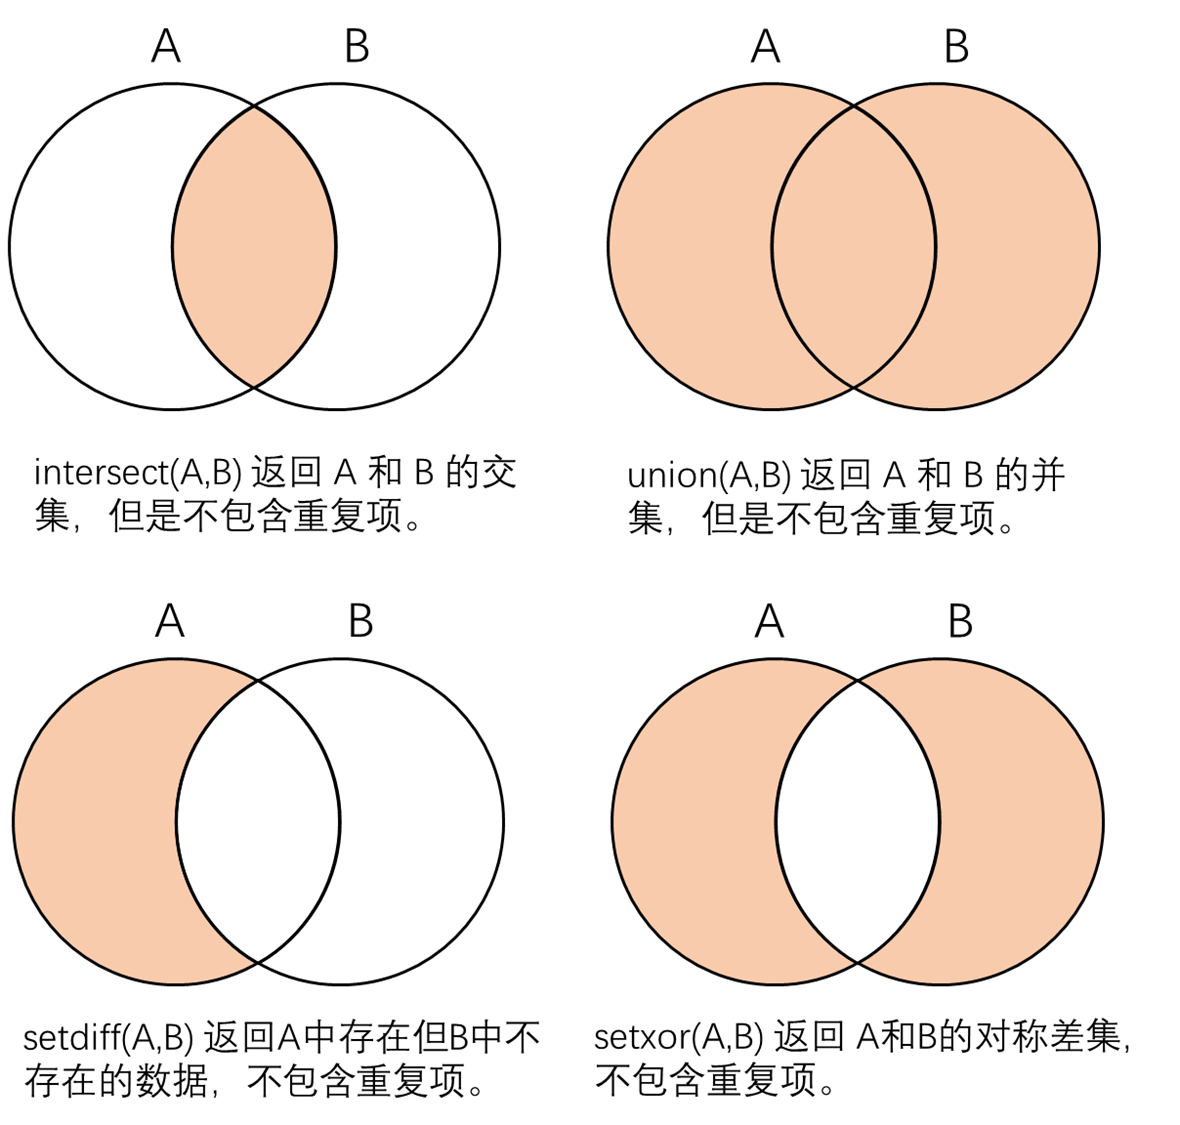

`因为这四个函数的用法类似，所以我们下面主要以`intersect`函数为例，介绍它们的用法。`

C = intersect(A,B)`会返回数组`A`和`B`的共同数据，但是不包含重复项，返回的`C`默认会排序。`

A = [5 3 1 4 2 7 2];
B = [2 8 6 1 0 3 9 5];
C = intersect(A,B)

C =      1     2     3     5


A = [1 2 4;
    3 4 8];
B = [1 3;
    8 7;
    1 2];
C = intersect(A,B) 

C =      1
     2
     3
     8


我们还可以增加一个输入参数'stable'，这样会按照在A中出现的顺序返回C中的值。

A = [5 3 1 4 2 7 2];
B = [2 8 6 1 0 3 9 5];
C = intersect(A,B,'stable')

C =      5     3     1     2


如果A和B的列数相同，那么我们可以加一个输入参数'rows'，这时候intersect (A, B, 'rows')会将A和B的每一行视为一个整体，然后找到公共的行。

A = [3 3 3;
     0 0 1; 
     1 0 3; 
     1 1 1];
B = [1 0 3; 
     3 3 3; 
     0 0 0];
C = intersect(A,B,'rows')

C =      1     0     3
     3     3     3


intersect函数可以有最多三个返回值

`[`[`C`](https://www.mathworks.com/help/releases/R2023a/matlab/ref/double.intersect.html?overload=intersect%20false&doclanguage=zh-CN&nocookie=true&prodfilter=ML%20CF%20GD%20MR%20TE%20OP%20DM%20PD%20ST&docviewer=helpbrowser&docrelease=R2023a&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DFYY5NM%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=NSKVG8&container=jshelpbrowser#btcnv0o-1-C)`,`[`ia`](https://www.mathworks.com/help/releases/R2023a/matlab/ref/double.intersect.html?overload=intersect%20false&doclanguage=zh-CN&nocookie=true&prodfilter=ML%20CF%20GD%20MR%20TE%20OP%20DM%20PD%20ST&docviewer=helpbrowser&docrelease=R2023a&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DFYY5NM%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=NSKVG8&container=jshelpbrowser#btcnv0o-1-ia)`,`[`ib`](https://www.mathworks.com/help/releases/R2023a/matlab/ref/double.intersect.html?overload=intersect%20false&doclanguage=zh-CN&nocookie=true&prodfilter=ML%20CF%20GD%20MR%20TE%20OP%20DM%20PD%20ST&docviewer=helpbrowser&docrelease=R2023a&s_cid=pl_webdoc&loginurl=https%3A%2F%2F127.0.0.1%3A31515%2Ftoolbox%2Fmatlab%2Flogin%2Fweb%2Findex.html%3Fsnc%3DFYY5NM%26external%3Dtrue%26channel%3D__mlfpmc__&searchsource=mw&snc=NSKVG8&container=jshelpbrowser#btcnv0o-1-ib)`] = intersect(``___``)` 还使用上述任何语法返回索引向量 `ia` 和 `ib`。

- 一般情况下，`C = A(ia)` 且 `C = B(ib)`。

- 如果指定了 `'rows'` 选项，则 `C = A(ia,:)` 且 `C = B(ib,:)`。

A = [5 3 1 4 2 7 2];
B = [2 8 6 1 0 3 9 5];
[C,ia,ib] = intersect(A,B)
A = [5 3 1 4 2 7 2];
B = [2 8 6 1 0 3 9 5];
[C,ia,ib] = intersect(A,B,'stable')
A = [3 3 3;
     0 0 1; 
     1 0 3; 
     1 1 1];
B = [1 0 3; 
     3 3 3; 
     0 0 0];
[C,ia,ib] = intersect(A,B,'rows')

剩余三个函数的用法我们各举一个简单的例子，大家可以自己查看帮助文档学习。

A = [5 3 1 7 2];
B = [2 8 6 1 5];
C = union(A,B)  % A和B的并集
A = [6 3;
     5 1;
     3 7];
B = [4 2;


    5 1];
C = union(A,B,'rows')  % A和B的并集
A = [5 3 1 7 2];
B = [2 8 6 1 5];
D1 = setdiff(A,B)  % A中有B中没有
D2 = setdiff(B,A)  % B中有A中没有
A = [5 3 1 7 2];
B = [2 8 6 1 5];
E = setxor(A,B)  % 出现在A或B中，但不是同时出现

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)